# Analysing time series poses with Transformer networks

## Load the data

% INIT
% Init Transformers

logger('Starting creating of transformer netowrk and test it', 'INFO');

[2025-02-17 09:43:47] [INFO] [acuna@PC175] Starting creating of transformer netowrk and test it


%{
 animal_list = {'326', '327', '328', '330', '332_training', '332', '334', '335', '336'};
 
%}

clc, clear

GC = general_configs(); % load general configurations

%% Load Data
logger('Loading data', 'INFO');

[2025-02-17 09:43:47] [INFO] [acuna@PC175] Loading data


% Load analysis structure
load(GC.filename_analysis, 'analysisstruct');

% Load predictions
load(GC.filename_predictions, 'predictions', 'animal_condition_identifier');

% Load ratception structure
% load(GC.filename_ratception, 'ratception_struct');

Load train data (baseline)

x = cat(2, analysisstruct.jt_features, analysisstruct.extra_jt_features);
% Load instead the cluster sequence
% x = cell2mat(analysisstruct.annot_reordered_matched)';
% x = pca(x', "NumComponents",1);
long_animal_frames_identifier = repelem(animal_condition_identifier,3);
animal_list_used_after_analysis =  long_animal_frames_identifier(analysisstruct.frames_with_good_tracking{1});

%%
% Find indices of strings ending with 'F' or 'S'
valid_idx = cellfun(@(x) endsWith(x, {'B'}), animal_list_used_after_analysis);

% Extract corresponding rows from x and get labels
xtrain = x(valid_idx, :);
l = cellfun(@(x) x(end), animal_list_used_after_analysis(valid_idx), 'UniformOutput', false);

% downsample
% x_sub = xtrain(1:10:end, :) ;
% l_sub = l(1:10:end,:);

Add prediction data

In this case we want to predict F

valid_idx = cellfun(@(x) endsWith(x, {'F'}), animal_list_used_after_analysis);

% Extract corresponding rows from x and get labels
xtest = x(valid_idx, :);
% xtest = pca(xtest', 'NumComponents',1);
ltest = cellfun(@(x) x(end), animal_list_used_after_analysis(valid_idx), 'UniformOutput', false);


Normalize data

## start protocol

nTest = length(xtest);
[x1, mu1, sigma1] = standardizeByCol(xtrain);
x2 = (xtest - mu1) ./ (sigma1);
xNorm = [x1; x2];

## when using the clusters.

% xNorm = [xtrain; xtest];

Create the feature variable, consisting of the price of each stock over the past 30 days.

windowSize = 30;
nrows = size(xNorm,1) - windowSize;
features = cell(nrows, 1);

for row = 1:nrows
    features{row} = xNorm(row:windowSize+row-1,:)';
end

Create the response variable, consisting of the price of each stock after each rolling 30 day window.

response = xNorm(windowSize+1:end,:);
nFeatures = size(xNorm,2);

Split the features and response variables into training and testing sets.

xTest = features(end-nTest+1:end,:);
yTest = response(end-nTest+1:end,:);

xTrain = features(1:end-nTest,:);
yTrain = response(1:end-nTest,:);

## Transfor the data

# Network creation

## Multihead attention network

lgraph = layerGraph();
tempLayers = sequenceInputLayer(nFeatures,"Name","sequenceinput");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = selfAttentionLayer(12,768,"Name","selfattention","AttentionMask","causal","DropoutProbability",0.001);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = selfAttentionLayer(12,768,"Name","selfattention_1","AttentionMask","causal","DropoutProbability",0.001);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = selfAttentionLayer(12,768,"Name","selfattention_2","AttentionMask","causal","DropoutProbability",0.001);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(3,"Name","addition")
    lstmLayer(128,"Name","lstm","OutputMode","last")
    fullyConnectedLayer(nFeatures,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

lgraph = connectLayers(lgraph,"sequenceinput","selfattention");
lgraph = connectLayers(lgraph,"sequenceinput","selfattention_1");
lgraph = connectLayers(lgraph,"sequenceinput","selfattention_2");
lgraph = connectLayers(lgraph,"selfattention","addition/in1");
lgraph = connectLayers(lgraph,"selfattention_1","addition/in2");
lgraph = connectLayers(lgraph,"selfattention_2","addition/in3");

lgraph_mhA = lgraph;

### Small Attention based network

numChannels = nFeatures;
maxPosition = 256;
numHeads = 4;
numKeyChannels = numHeads*32;

layers = [ 
    sequenceInputLayer(numChannels,Name="input")
    positionEmbeddingLayer(1,maxPosition,Name="pos-emb");
    additionLayer(2, Name="add")
    selfAttentionLayer(numHeads,numKeyChannels,'AttentionMask','causal')
    selfAttentionLayer(numHeads,numKeyChannels)
    indexing1dLayer("last")
    fullyConnectedLayer(numChannels)
    regressionLayer];

lgraph = layerGraph(layers);
lgraph_small = connectLayers(lgraph,"input","add/in2");

% taken from 
% https://blogs.mathworks.com/deep-learning/2024/11/12/how-to-design-transformer-model-for-time-series-forecasting/

### **Decoder-Only Transformer Design**

numFeatures = nFeatures;
numHeads = 4; 
numKeyChannels = 256; 
feedforwardHiddenSize = 512; 
modelHiddenSize = 256; 
maxSequenceLength = 120;

lgraph = layerGraph();

decoderLayers = [ 
    sequenceInputLayer(numFeatures, Name="in")
    fullyConnectedLayer(modelHiddenSize, Name="embedding")
    positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="position_embed") 
    additionLayer(2, Name="embed_add") 
    layerNormalizationLayer(Name="embed_norm") 
    selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal") 
    additionLayer(2, Name="attention_add") 
    layerNormalizationLayer(Name="attention_norm") 
    fullyConnectedLayer(feedforwardHiddenSize) 
    geluLayer 
    fullyConnectedLayer(modelHiddenSize) 
    additionLayer(2, Name="feedforward_add") 
    layerNormalizationLayer(Name="decoder1_norm") 
    selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal") 
    additionLayer(2, Name="attention2_add") 
    layerNormalizationLayer(Name="attention2_norm") 
    fullyConnectedLayer(feedforwardHiddenSize) 
    geluLayer 
    fullyConnectedLayer(modelHiddenSize) 
    additionLayer(2, Name="feedforward2_add") 
    layerNormalizationLayer(Name="decoder2_norm") 
    lstmLayer(128,"Name","lstm","OutputMode","last")
    fullyConnectedLayer(numFeatures, Name="head")
    regressionLayer(Name="regressionoutput")];

lgraph = addLayers(lgraph,decoderLayers);


lgraph = connectLayers(lgraph,"embedding","embed_add/in2");
lgraph = connectLayers(lgraph,"embed_norm","attention_add/in2");
lgraph = connectLayers(lgraph,"attention_norm","feedforward_add/in2");
lgraph = connectLayers(lgraph,"decoder1_norm","attention2_add/in2");
lgraph = connectLayers(lgraph,"attention2_norm","feedforward2_add/in2");

lgraph_decoder = lgraph;

### 4x Transformer decoder

% % Network parameters (you already have these)
% numFeatures = nFeatures;
% numHeads = 4;
% numKeyChannels = 256;
% feedforwardHiddenSize = 512;
% modelHiddenSize = 256;
% maxSequenceLength = 120;
% 
% % New parameters matching Python code
% numTransformerBlocks = 4;  % Number of transformer blocks
% mlpUnits = [128 64];      % Size of MLP layers after transformer
% 
% lgraph = layerGraph();
% 
% % Initial layers
% initialLayers = [
%     sequenceInputLayer(numFeatures, Name="in")
%     fullyConnectedLayer(modelHiddenSize, Name="embedding")
%     positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="position_embed")
%     additionLayer(2, Name="embed_add")
%     layerNormalizationLayer(Name="embed_norm")];
% 
% lgraph = addLayers(lgraph, initialLayers);
% 
% % Connect embedding to add layer
% lgraph = connectLayers(lgraph, "embedding", "embed_add/in2");
% 
% % Add multiple transformer blocks
% for i = 1:numTransformerBlocks
%     blockName = "block" + i;
% 
%     transformerBlock = [
%         selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal", Name=blockName+"_attention")
%         additionLayer(2, Name=blockName+"_attention_add")
%         layerNormalizationLayer(Name=blockName+"_attention_norm")
%         fullyConnectedLayer(feedforwardHiddenSize, Name=blockName+"_ff1")
%         geluLayer(Name=blockName+"_gelu")
%         fullyConnectedLayer(modelHiddenSize, Name=blockName+"_ff2")
%         additionLayer(2, Name=blockName+"_ffn_add")
%         layerNormalizationLayer(Name=blockName+"_final_norm")];
% 
%     lgraph = addLayers(lgraph, transformerBlock);
% 
%     % Connect layers between blocks
%     if i == 1
%         lgraph = connectLayers(lgraph, "embed_norm", blockName+"_attention");
%     else
%         prevBlock = "block" + (i-1) + "_final_norm";
%         lgraph = connectLayers(lgraph, prevBlock, blockName+"_attention");
%     end
% 
%     % Add residual connections within block
%     lgraph = connectLayers(lgraph, blockName+"_attention", blockName+"_attention_add/in2");
%     lgraph = connectLayers(lgraph, blockName+"_attention_norm", blockName+"_ffn_add/in2");
% end
% 
% % Connect last transformer block to GAP
% % lstmLayer(128,"Name","lstm","OutputMode","last")
% lgraph = addLayers(lgraph, globalAveragePooling1dLayer(Name="gap"));
% lgraph = connectLayers(lgraph, "block"+numTransformerBlocks+"_final_norm", "gap");
% 
% % Add MLP layers
% prevLayer = "gap";
% for i = 1:length(mlpUnits)
%     mlpName = "mlp" + i;
%     mlpBlock = [
%         lstmLayer(128,Name=mlpName+"_lstm")
%         fullyConnectedLayer(mlpUnits(i), Name=mlpName+"_dense")
%         reluLayer(Name=mlpName+"_relu")
%         dropoutLayer(0.1, Name=mlpName+"_dropout")];
% 
%     lgraph = addLayers(lgraph, mlpBlock);
%     lgraph = connectLayers(lgraph, prevLayer, mlpName+"_lstm");
%     prevLayer = mlpName+"_dropout";
% end
% 
% % Output layer
% outputLayers = [
%     fullyConnectedLayer(numFeatures, Name="head")
%     regressionLayer(Name="regressionoutput")];
% 
% lgraph = addLayers(lgraph, outputLayers);
% lgraph = connectLayers(lgraph, prevLayer, "head");
% lgraph_big = lgraph;

lgraph = layerGraph();

% Initial layers
initialLayers = [
    sequenceInputLayer(numFeatures, Name="in")
    fullyConnectedLayer(modelHiddenSize, Name="embedding")
    positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="position_embed")
    additionLayer(2, Name="embed_add")
    layerNormalizationLayer(Name="embed_norm")];

lgraph = addLayers(lgraph, initialLayers);
lgraph = connectLayers(lgraph, "embedding", "embed_add/in2");

% Add multiple transformer blocks
for i = 1:numTransformerBlocks
    blockName = "block" + i;
    
    transformerBlock = [
        selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal", Name=blockName+"_attention")
        additionLayer(2, Name=blockName+"_attention_add")
        layerNormalizationLayer(Name=blockName+"_attention_norm")
        fullyConnectedLayer(feedforwardHiddenSize, Name=blockName+"_ff1")
        geluLayer(Name=blockName+"_gelu")
        fullyConnectedLayer(modelHiddenSize, Name=blockName+"_ff2")
        additionLayer(2, Name=blockName+"_ffn_add")
        layerNormalizationLayer(Name=blockName+"_final_norm")];
    
    lgraph = addLayers(lgraph, transformerBlock);
    
    % Connect layers between blocks
    if i == 1
        lgraph = connectLayers(lgraph, "embed_norm", blockName+"_attention");
    else
        prevBlock = "block" + (i-1) + "_final_norm";
        lgraph = connectLayers(lgraph, prevBlock, blockName+"_attention");
    end
    
    % Add residual connections within block
    lgraph = connectLayers(lgraph, blockName+"_attention", blockName+"_attention_add/in2");
    lgraph = connectLayers(lgraph, blockName+"_attention_norm", blockName+"_ffn_add/in2");
end

% Replace GAP with LSTM
lgraph = addLayers(lgraph, [
    lstmLayer(128, Name="lstm", OutputMode="last")
    fullyConnectedLayer(numFeatures, Name="head")
    regressionLayer(Name="regressionoutput")]);

% Connect last transformer block to LSTM
lgraph_big = connectLayers(lgraph, "block"+numTransformerBlocks+"_final_norm", "lstm");

numTransformerBlocks = 4;  % Number of transformer blocks
mlpUnits = [128 64];      % Size of MLP layers after transformer

% encoder and decoder
lgraph = layerGraph();

% Single input 
initialLayers = [
    sequenceInputLayer(numFeatures, Name="in")];
lgraph = addLayers(lgraph, initialLayers);

% Encoder path initial layers
encoderInitial = [
    fullyConnectedLayer(modelHiddenSize, Name="encoder_embedding")
    positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="encoder_pos_embed")
    additionLayer(2, Name="encoder_embed_add")
    layerNormalizationLayer(Name="encoder_embed_norm")];

lgraph = addLayers(lgraph, encoderInitial);
lgraph = connectLayers(lgraph, "in", "encoder_embedding");
lgraph = connectLayers(lgraph, "encoder_embedding", "encoder_embed_add/in2");

% Encoder blocks
for i = 1:numTransformerBlocks
    blockName = "encoder_block" + i;
    
    encoderBlock = [
        selfAttentionLayer(numHeads, numKeyChannels, Name=blockName+"_attention")
        additionLayer(2, Name=blockName+"_attention_add")
        layerNormalizationLayer(Name=blockName+"_attention_norm")
        fullyConnectedLayer(feedforwardHiddenSize, Name=blockName+"_ff1")
        geluLayer(Name=blockName+"_gelu")
        fullyConnectedLayer(modelHiddenSize, Name=blockName+"_ff2")
        additionLayer(2, Name=blockName+"_ffn_add")
        layerNormalizationLayer(Name=blockName+"_final_norm")];
    
    lgraph = addLayers(lgraph, encoderBlock);
    
    if i == 1
        lgraph = connectLayers(lgraph, "encoder_embed_norm", blockName+"_attention");
    else
        prevBlock = "encoder_block" + (i-1) + "_final_norm";
        lgraph = connectLayers(lgraph, prevBlock, blockName+"_attention");
    end
    
    lgraph = connectLayers(lgraph, blockName+"_attention", blockName+"_attention_add/in2");
    lgraph = connectLayers(lgraph, blockName+"_attention_norm", blockName+"_ffn_add/in2");
end

encoderFinalLayer = "encoder_block" + numTransformerBlocks + "_final_norm";

% Decoder path initial layers
decoderInitial = [
    fullyConnectedLayer(modelHiddenSize, Name="decoder_embedding")
    positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="decoder_pos_embed")
    additionLayer(2, Name="decoder_embed_add")
    layerNormalizationLayer(Name="decoder_embed_norm")];

lgraph = addLayers(lgraph, decoderInitial);
lgraph = connectLayers(lgraph, "in", "decoder_embedding");
lgraph = connectLayers(lgraph, "decoder_embedding", "decoder_embed_add/in2");

% Decoder blocks
for i = 1:numTransformerBlocks
    blockName = "decoder_block" + i;
    
    decoderBlock = [
        selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal", Name=blockName+"_attention")
        additionLayer(2, Name=blockName+"_attention_add")
        layerNormalizationLayer(Name=blockName+"_attention_norm")
        concatenationLayer(1, 2, Name=blockName+"_concat")
        fullyConnectedLayer(modelHiddenSize, Name=blockName+"_combine")
        layerNormalizationLayer(Name=blockName+"_combine_norm")
        fullyConnectedLayer(feedforwardHiddenSize, Name=blockName+"_ff1")
        geluLayer(Name=blockName+"_gelu")
        fullyConnectedLayer(modelHiddenSize, Name=blockName+"_ff2")
        additionLayer(2, Name=blockName+"_ffn_add")
        layerNormalizationLayer(Name=blockName+"_final_norm")];
    
    lgraph = addLayers(lgraph, decoderBlock);
    
    if i == 1
        lgraph = connectLayers(lgraph, "decoder_embed_norm", blockName+"_attention");
    else
        prevBlock = "decoder_block" + (i-1) + "_final_norm";
        lgraph = connectLayers(lgraph, prevBlock, blockName+"_attention");
    end
    
    lgraph = connectLayers(lgraph, encoderFinalLayer, blockName+"_concat/in2");
    lgraph = connectLayers(lgraph, blockName+"_attention", blockName+"_attention_add/in2");
    lgraph = connectLayers(lgraph, blockName+"_combine_norm", blockName+"_ffn_add/in2");
end

% Output layers
lgraph = addLayers(lgraph, [
    lstmLayer(128, Name="lstm", OutputMode="last")
    fullyConnectedLayer(numFeatures, Name="head")
    regressionLayer(Name="regressionoutput")]);

lgraph_big_e_d = connectLayers(lgraph, "decoder_block"+numTransformerBlocks+"_final_norm", "lstm");

% net = connectLayers(net,"embedding","embed_add/in2");
% net = connectLayers(net,"embed_norm","attention_add/in2");
% net = connectLayers(net,"attention_norm","feedforward_add/in2");
% net = connectLayers(net,"decoder1_norm","attention2_add/in2");
% net = connectLayers(net,"attention2_norm","feedforward2_add/in2");

% net = initialize(net);

% analyzeNetwork(net)

% netTrained = trainnet(xTrain,yTrain,net,'crossentropy',options);

% net = dlnetwork(lgraph,Initialize=true);

% net2 = trainNetwork(xTrain,yTrain,net,options);


xTest = features(end-nTest+1:end,:);
yTest = response(end-nTest+1:end,:);

xTrain = features(1:end-nTest,:);
yTrain = response(1:end-nTest,:);

% First, let's check sizesnetTrained = trainnet(XTrain,YTrain,net,'crossentropy',options);

options = trainingOptions(solver, ...
    'Plots','training-progress', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', shuffle, ...
    'InitialLearnRate', learningRate, ...
    'GradientThreshold', gradientThreshold, ...
    'ExecutionEnvironment', executionEnvironment);

## **1. small**

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |        10.05 |         50.5 |          0.0010 |
|       1 |          50 |       00:00:04 |         6.91 |         23.9 |          0.0010 |
|       1 |         100 |       00:00:07 |         6.33 |         20.0 |          0.0010 |
|       1 |         150 |       00:00:10 |         5.84 |         17.1 |          0.0010 |
|       1 |         200 |       00:00:13 |         5.73 |         16.4 |          0.0010 |
|       1 |         250 |       00:00:16 |         4.42 |          9.8 |          0.0010 |
|       1 |         300 |       00:00:19 |         4.06 |          8.2 |          0.0010 |

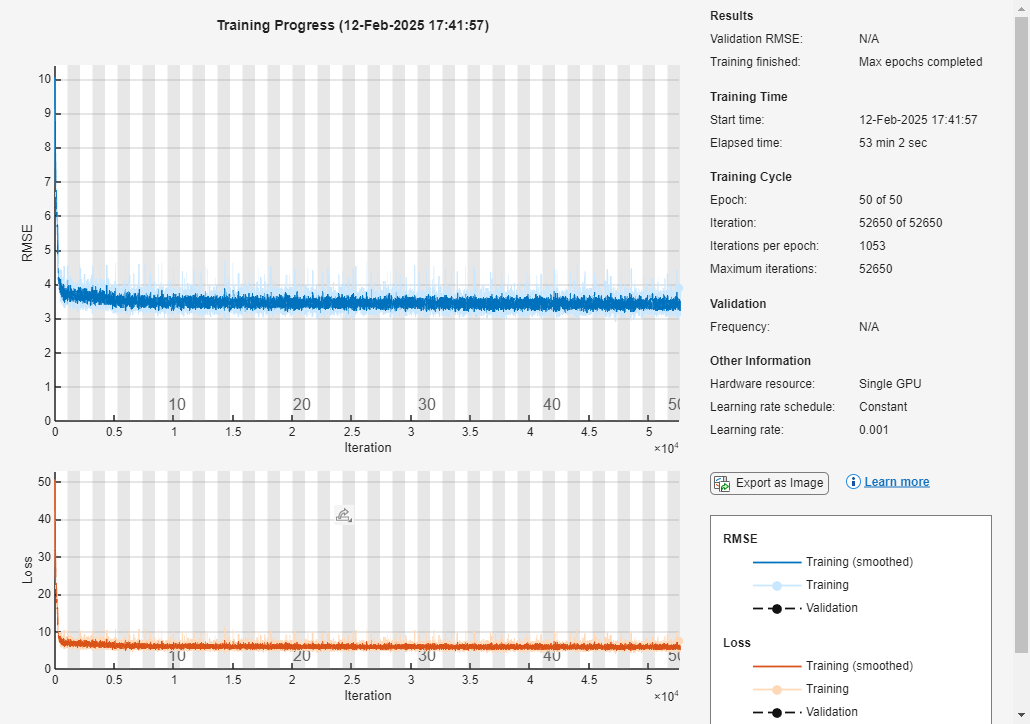

net_small = trainNetwork(xTrain, yTrain, lgraph_small, options); % 

yPredTrain_small = predict(net_small, xTrain);

## **2. 4x Transformer**

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         8.60 |         36.9 |          0.0010 |
|       1 |          50 |       00:00:07 |         6.99 |         24.4 |          0.0010 |
|       1 |         100 |       00:00:13 |         6.48 |         21.0 |          0.0010 |
|       1 |         150 |       00:00:19 |         6.31 |         19.9 |          0.0010 |
|       1 |         200 |       00:00:25 |         6.00 |         18.0 |          0.0010 |
|       1 |         250 |       00:00:30 |         5.77 |         16.7 |          0.0010 |
|       1 |         300 |       00:00:37 |         5.80 |         16.8 |          0.0010 |

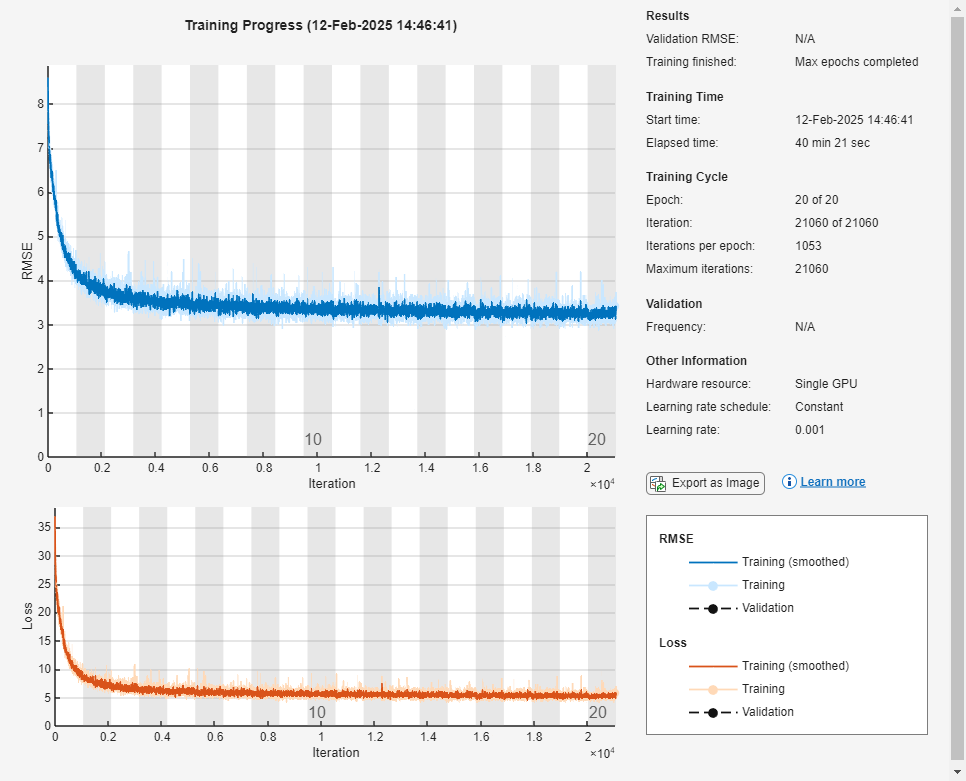

net_big = trainNetwork(xTrain, yTrain, lgraph_big, options); % 

yPredTrain_big = predict(net_big, xTrain);

## **3. 4x Transformer - Encoder & decoder**

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         8.78 |         38.5 |          0.0010 |
|       1 |          50 |       00:00:11 |         7.02 |         24.6 |          0.0010 |
|       1 |         100 |       00:00:22 |         6.40 |         20.5 |          0.0010 |
|       1 |         150 |       00:00:33 |         5.69 |         16.2 |          0.0010 |
|       1 |         200 |       00:00:43 |         5.36 |         14.4 |          0.0010 |
|       1 |         250 |       00:00:54 |         4.74 |         11.2 |          0.0010 |
|       1 |         300 |       00:01:05 |         4.50 |         10.1 |          0.0010 |

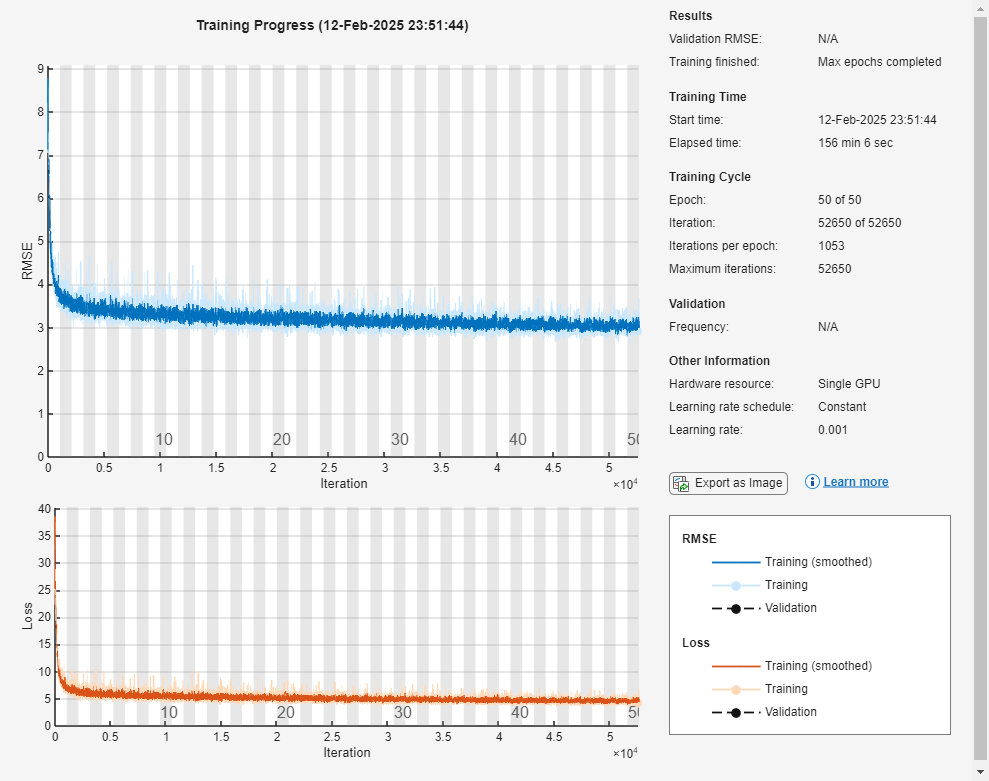

net_big_e_d = trainNetwork(xTrain, yTrain, lgraph_big_e_d, options); % 

yPredTrain_big_e_d = predict(net_big_e_d, xTrain);

## **4. Decoder-Only Transformer Design**

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         8.52 |         36.3 |          0.0010 |
|       1 |          50 |       00:00:04 |         5.54 |         15.4 |          0.0010 |
|       1 |         100 |       00:00:07 |         4.46 |          9.9 |          0.0010 |
|       1 |         150 |       00:00:11 |         3.90 |          7.6 |          0.0010 |
|       1 |         200 |       00:00:15 |         4.07 |          8.3 |          0.0010 |
|       1 |         250 |       00:00:19 |         3.90 |          7.6 |          0.0010 |
|       1 |         300 |       00:00:23 |         3.83 |          7.3 |          0.0010 |

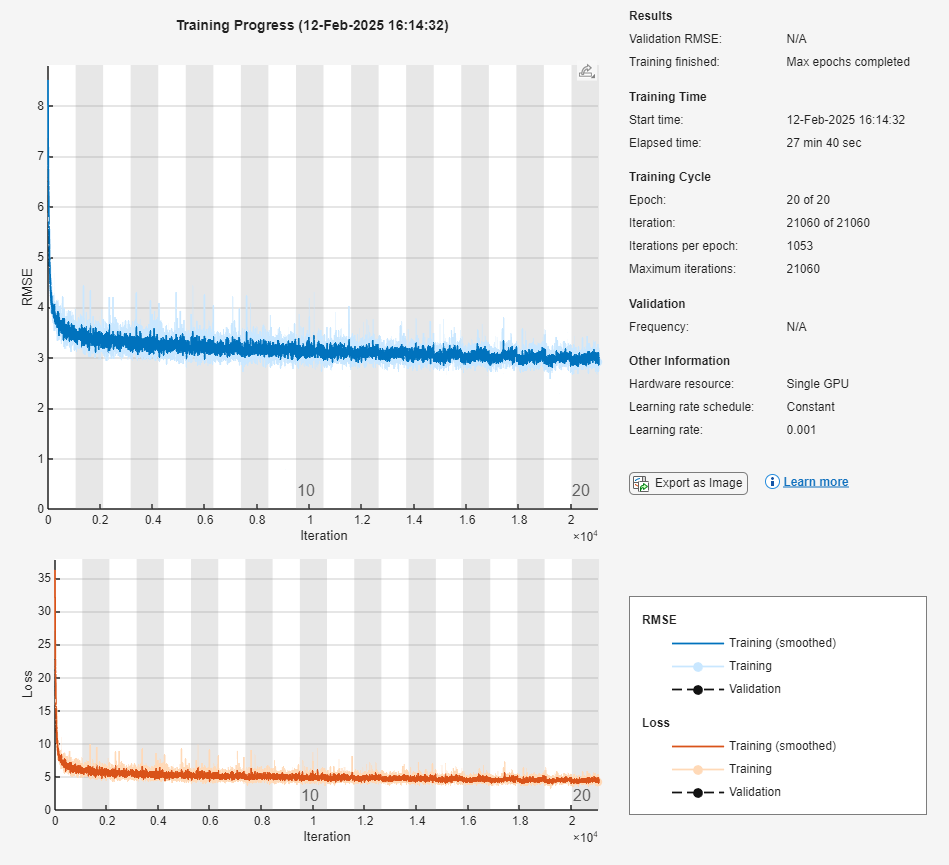

net_decoder = trainNetwork(xTrain, yTrain, lgraph_decoder, options); % train big net

yPredTrain_decoder = predict(net_decoder, xTrain);

## **5. Multihead Self-Attention LSTM Network**

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         8.23 |         33.8 |          0.0010 |
|       1 |          50 |       00:00:05 |         6.46 |         20.9 |          0.0010 |
|       1 |         100 |       00:00:08 |         5.98 |         17.9 |          0.0010 |
|       1 |         150 |       00:00:12 |         5.10 |         13.0 |          0.0010 |
|       1 |         200 |       00:00:15 |         4.58 |         10.5 |          0.0010 |
|       1 |         250 |       00:00:19 |         4.72 |         11.1 |          0.0010 |
|       1 |         300 |       00:00:22 |         4.17 |          8.7 |          0.0010 |

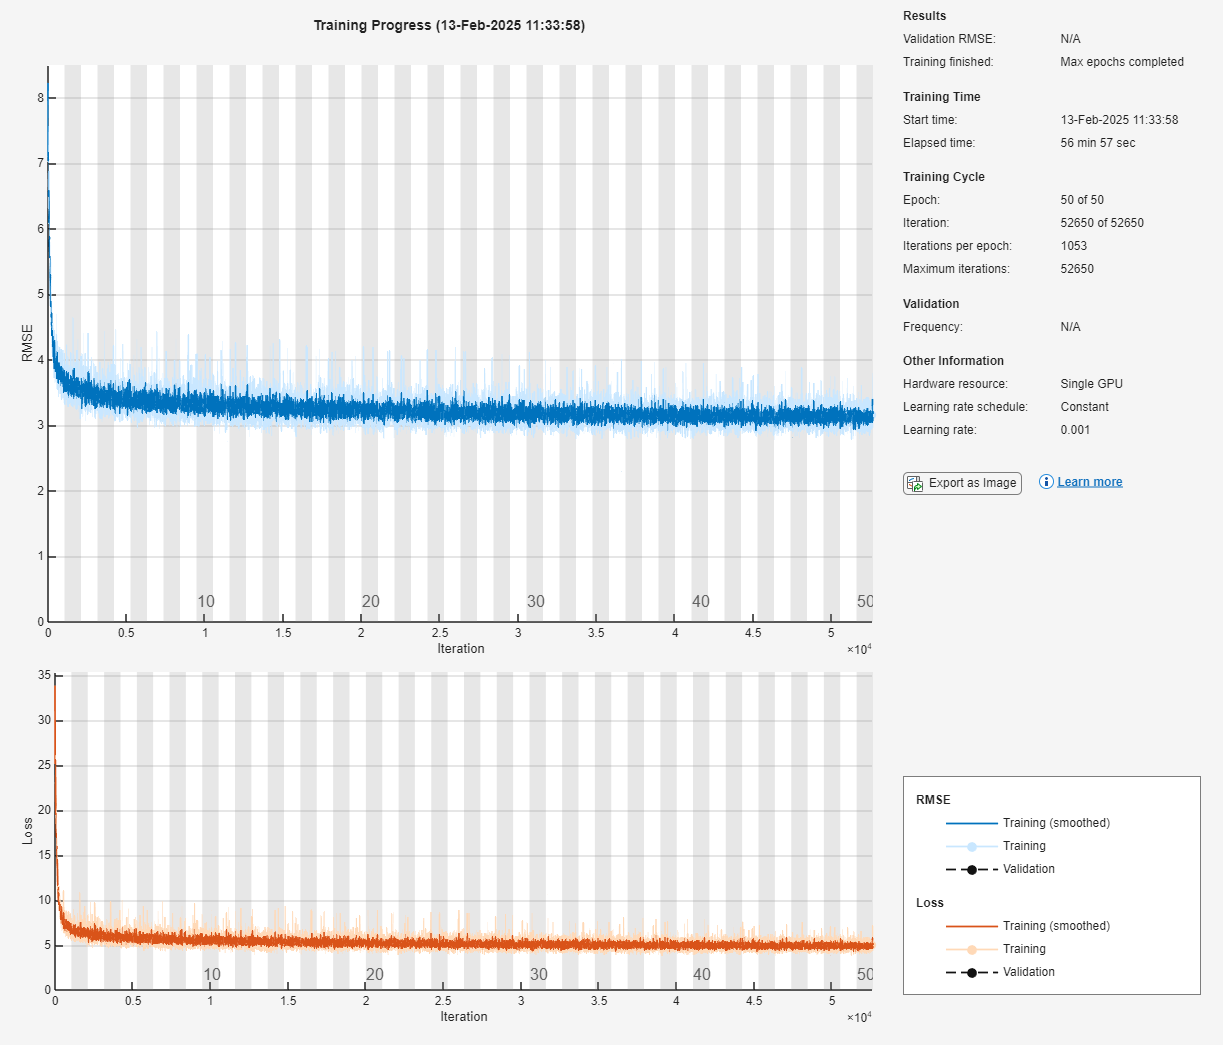

net_mhA = trainNetwork(xTrain, yTrain, lgraph_mhA, options); % train big net

% netTrained = trainnet(xTrant,yTrainCell,net,'crossentropy',options);
yPredTrain_mhA = predict(net_mhA, xTrain);

Test both networks


% yPredTrain = predict(net_1, xTrain);
% net_mhA


% Run re-conversion
sigma = sigma1;
mu = mu1;

predictTrain = yPredTrain.*sigma + mu;
predictTrain_big = yPredTrain_big.*sigma + mu;
predictTrain_big_e_d = yPredTrain_big_e_d.*sigma + mu;
predictTrain_small = yPredTrain_small.*sigma + mu;
predictTrain_decoder = yPredTrain_decoder.*sigma + mu;
predictTrain_mhA = yPredTrain_mhA.*sigma + mu;

% actual
actualTrain = yTrain.*sigma + mu;

% do RMSE
RMSE_Train = sqrt(mean((actualTrain - predictTrain).^2))

RMSE_Train = 1×66 single row vector
    0.0944    0.1931    0.1938    0.1766    0.2499    0.2736    0.2538    0.2405    0.3113    0.3642    0.3478    0.3345    0.2887    0.3128    0.3674    0.0925    0.2095    0.1996    0.1954    0.2221    0.3261    0.2956    0.3458    0.3201    0.3748    0.4063    0.4112    0.3351    0.3413    0.3298    0.4349    0.5124    0.3357    0.3926    0.4871    0.4608    0.5308    0.5657    0.6231    0.5958    0.3138    0.4330    0.4433    0.3765    0.4158    0.5111    0.4904    0.5193    0.6045    0.5293


% RMSE_Train_big = sqrt(mean((actualTrain - predictTrain_big)))
RMSE_Train_big = real(sqrt(mean((actualTrain - predictTrain_big).^2)))

RMSE_Train_big = 1×66 single row vector
    0.1557    0.2517    0.2361    0.2240    0.2708    0.3007    0.2764    0.2553    0.3352    0.3842    0.3802    0.3505    0.3095    0.3346    0.3779    0.1525    0.2564    0.2339    0.2421    0.2534    0.3486    0.3132    0.3554    0.3352    0.3909    0.4228    0.4251    0.3577    0.3549    0.3419    0.4763    0.5959    0.3731    0.4274    0.5359    0.5000    0.5698    0.6046    0.6666    0.6423    0.3397    0.4754    0.4889    0.4204    0.4570    0.5621    0.5393    0.5765    0.6753    0.5732


RMSE_Train_big_e_d = real(sqrt(mean((actualTrain - predictTrain_big_e_d).^2)))

RMSE_Train_big_e_d = 1×66 single row vector
    0.1243    0.2106    0.2050    0.1913    0.2605    0.2829    0.2677    0.2552    0.3183    0.3715    0.3640    0.3415    0.3081    0.3229    0.3734    0.1259    0.2282    0.2103    0.2118    0.2334    0.3392    0.3054    0.3507    0.3378    0.3837    0.4160    0.4167    0.3469    0.3510    0.3343    0.4342    0.5221    0.3483    0.3998    0.4970    0.4702    0.5405    0.5784    0.6387    0.6060    0.3187    0.4439    0.4605    0.3887    0.4315    0.5249    0.4971    0.5321    0.6140    0.5388


RMSE_Train_small = real(sqrt(mean((actualTrain - predictTrain_small).^2)))

RMSE_Train_small = 1×66 single row vector
    0.1077    0.2642    0.2392    0.2124    0.2804    0.3440    0.3174    0.2718    0.3562    0.4263    0.3932    0.3770    0.3294    0.3555    0.4106    0.1058    0.2776    0.2345    0.2281    0.2515    0.4010    0.3330    0.3691    0.3555    0.4191    0.4534    0.4612    0.3664    0.3732    0.3689    0.4861    0.6327    0.3959    0.4310    0.5596    0.5065    0.5978    0.6276    0.6981    0.6660    0.4494    0.5255    0.5236    0.4574    0.4919    0.5928    0.5893    0.6040    0.7179    0.6182


RMSE_Train_decoder = real(sqrt(mean((actualTrain - predictTrain_decoder).^2)))

RMSE_Train_decoder = 1×66 single row vector
    0.1064    0.1905    0.1921    0.1757    0.2507    0.2679    0.2513    0.2369    0.3093    0.3620    0.3491    0.3324    0.2862    0.3124    0.3599    0.0977    0.2102    0.1923    0.1938    0.2189    0.3285    0.2971    0.3408    0.3207    0.3742    0.4060    0.4107    0.3318    0.3415    0.3298    0.4339    0.5113    0.3317    0.3921    0.4838    0.4582    0.5329    0.5661    0.6203    0.5952    0.3247    0.4320    0.4441    0.3719    0.4154    0.5125    0.4881    0.5237    0.6056    0.5281


RMSE_Train_mhA = real(sqrt(mean((actualTrain - predictTrain_mhA).^2)))

RMSE_Train_mhA = 1×66 single row vector
    0.1141    0.2142    0.2188    0.1961    0.2616    0.2886    0.2688    0.2535    0.3283    0.3884    0.3664    0.3523    0.3105    0.3313    0.3845    0.1115    0.2324    0.2146    0.2160    0.2437    0.3514    0.3147    0.3588    0.3383    0.3929    0.4263    0.4325    0.3603    0.3607    0.3544    0.4584    0.5317    0.3539    0.4165    0.5059    0.4809    0.5612    0.6026    0.6656    0.6305    0.3454    0.4688    0.4773    0.3989    0.4454    0.5497    0.5181    0.5575    0.6462    0.5558


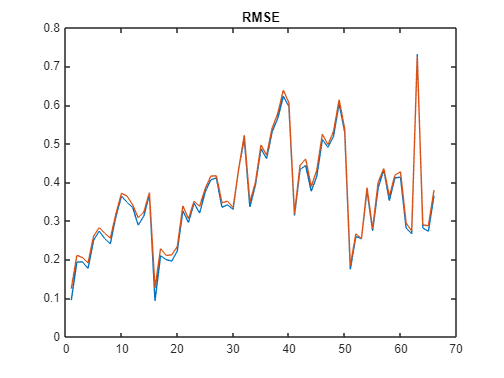

figure
plot(RMSE_Train); hold on, plot(RMSE_Train_big_e_d)
title('RMSE')

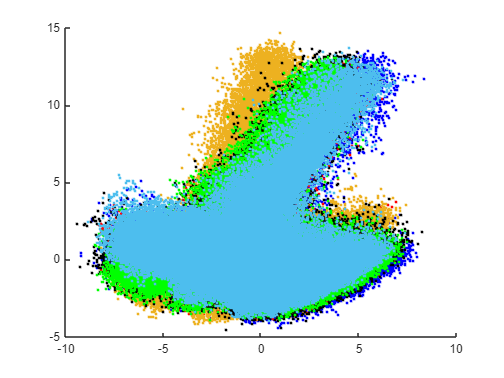

rng default
% Do dim reduction to compare both types of predictions
[~,pca_big] = pca(predictTrain_big, 'NumComponents',2);
[~,pca_small] = pca(predictTrain_small, 'NumComponents',2);
[~ ,pca_real] = pca(actualTrain, 'NumComponents',2);
[~,pca_decoder] = pca(predictTrain_decoder, 'NumComponents',2);
[~,pca_big_e_d] = pca(predictTrain_big_e_d, 'NumComponents',2);
[~,pca_big_mhA] = pca(predictTrain_mhA, 'NumComponents',2);

figure
scatter(pca_small(:,1), pca_small(:,2), '.b')
hold on
scatter(pca_big(:,1), pca_big(:,2), '.r')
scatter(pca_big_e_d(:,1), pca_big_e_d(:,2), 'color', [0.75, .75 .75], 'Marker','.')
scatter(pca_real(:,1), pca_real(:,2), '.k')
scatter(pca_decoder(:,1), pca_decoder(:,2), '.gr')
scatter(pca_big_mhA(:,1), pca_big_mhA(:,2), 'color', [0.25, .25 .25], 'Marker','.')

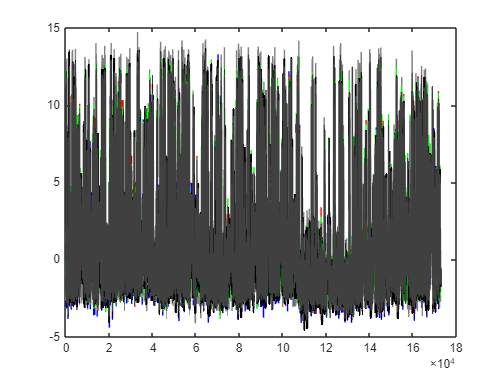


figure, 
plot(pca_small(:,2), 'b')
hold on
plot(pca_big(:,2), 'r')
plot(pca_big_e_d(:,2), 'color', [.5 .5 .5] )
plot(pca_decoder(:,2), 'gr')
plot(pca_real(:,2), 'k', 'LineWidth',2)
plot(pca_big_mhA(:,2),'color', [.25 .25 .25])


disp(['Corr : pca_big_mhA: ', num2str(corr(pca_big_mhA(:,1), pca_real(:,1)))])

Corr : pca_big_mhA: 0.97608


% corr(pca_big(:,2), pca_real(:,2))
disp(['Corr : pca_big: ', num2str(corr(pca_big(:,1), pca_real(:,1)))])

Corr : pca_big: 0.98407


% corr(pca_big_e_d(:,2), pca_real(:,2))
disp(['Corr : pca_big_e_d: ', num2str(corr(pca_big_e_d(:,1), pca_real(:,1)))])

Corr : pca_big_e_d: 0.94951


% corr(pca_decoder(:,2), pca_real(:,2))
disp(['Corr : pca_decoder: ', num2str(corr(pca_decoder(:,1), pca_real(:,1)))])

Corr : pca_decoder: 0.98839


% corr(pca_small(:,2), pca_real(:,2))
disp(['Corr : pca_small: ', num2str(corr(pca_small(:,1), pca_real(:,1)))])

Corr : pca_small: 0.97383




% Corr over all features
disp('Corr over all features')

Corr over all features


disp(['Corr : predictTrain_big: ', num2str(mean(diag(corr(predictTrain_big, actualTrain))))])

Corr : predictTrain_big: 0.91678


disp(['Corr : predictTrain_small: ', num2str(mean(diag(corr(predictTrain_small, actualTrain))))])

Corr : predictTrain_small: 0.90471


disp(['Corr : predictTrain_decoder: ', num2str(mean(diag(corr(predictTrain_decoder, actualTrain))))])

Corr : predictTrain_decoder: 0.93209


disp(['Corr : predictTrain_big_e_d: ', num2str(mean(diag(corr(predictTrain_big_e_d, actualTrain))))])

Corr : predictTrain_big_e_d: 0.92829


disp(['Corr : predictTrain_mhA: ', num2str(mean(diag(corr(predictTrain_mhA, actualTrain))))])

Corr : predictTrain_mhA: 0.92292



% it seems that the decoder net has the higher score

tsne_big_e_d = tsne(predictTrain_big_e_d, 'Verbose',1);


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.582841e+01 |    3.570172e-09 |
|       40 |    3.582841e+01 |    1.391905e-08 |
|       60 |    3.582841e+01 |    1.884298e-07 |
|       80 |    3.582698e+01 |    6.043131e-06 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    7.526688e+00 |    1.099187e-05 |
|      120 |    6.583786e+00 |    8.835155e-06 |
|      140 |    6.147462e+00 |    7.210496e-06 |
|      160 |    5.876484e+00 |    7.645323e-06 |
|      180 |    5.676674e+00 |    7.679444e-06 |
|      200 |    5.516441e+00 |    7.009698e-06 |
|      220 |    5.

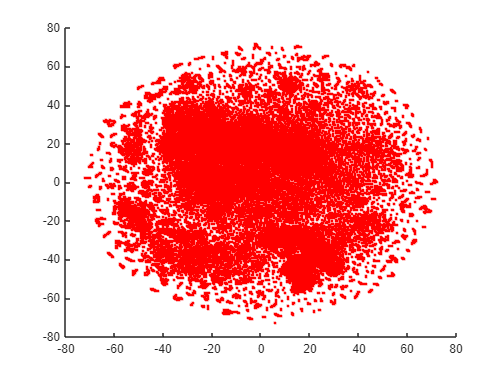

figure, scatter(tsne_big_e_d(:,1), tsne_big_e_d(:,2), 'r.')

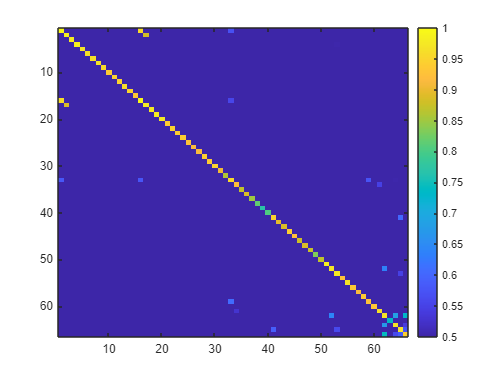

c = corr(predictTrain_big_e_d,actualTrain );
figure, imagesc(c)
clim([0.5 1])
colorbar

## TEST network

It seems that the encoder decoder worked well, as seen from the pca data, so let's predic the test data too

% yPredTrain = predict(net, xTrain);
yPredTrain_big_e_d_test = predict(net_big_e_d, xTest);


% normalize
predictTese_big_e_d = yPredTrain_big_e_d_test.*sigma + mu;
actualTest = yTest.*sigma + mu;
RMSE_Test_big_e_d = real(sqrt(mean((actualTest - predictTese_big_e_d).^2)))

RMSE_Test_big_e_d = 1×66 single row vector
    0.1199    0.2166    0.2078    0.1829    0.2470    0.2641    0.2436    0.2495    0.3193    0.3578    0.3619    0.3287    0.3163    0.3141    0.3699    0.1430    0.2362    0.2156    0.2093    0.2281    0.3403    0.3281    0.3525    0.3447    0.3811    0.4128    0.4322    0.3472    0.3546    0.3338    0.4901    0.6044    0.3232    0.3851    0.5028    0.4621    0.5511    0.6105    0.6304    0.6291    0.4426    0.4161    0.4561    0.3953    0.4114    0.4882    0.4889    0.4664    0.5082    0.4977


## Do PCA

rng default
% Do dim reduction to compare both types of predictions
[~,pca_big_e_d_test,  ~, ~, explained_test] = pca(predictTese_big_e_d, 'NumComponents',3);
[~, pca_real_test, ~, ~, explained_ac] = pca(actualTest, 'NumComponents',3);
mean_RMSE = mean(RMSE_Test_big_e_d(1:find(cumsum(explained_test) > 80, 1, 'first')));
disp([ 'mean RMSE to 80% var: ', num2str(mean_RMSE)])

mean RMSE to 80% var: 0.28044


### Figure PCA - Test data

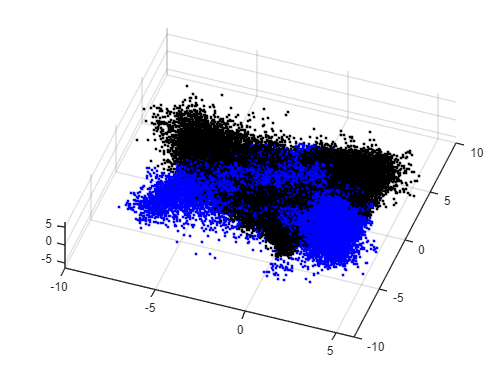

close;
figure
cla
scatter3(pca_real_test(:,1),pca_real_test(:,2),pca_real_test(:,3),'k.') %
hold on
scatter3(pca_big_e_d_test(:,1), pca_big_e_d_test(:,2),pca_big_e_d_test(:,3), 'b.') %  
hold off

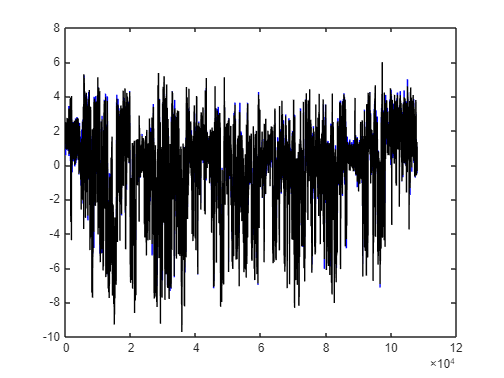


figure, 
plot(pca_big_e_d_test(:,1), 'b')
hold on
plot(pca_real_test(:,1), 'k')

Do tsne on test data

rng default
tsne_actualTest = tsne(actualTest, 'Verbose',1);


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.774032e+01 |    6.988320e-09 |
|       40 |    3.774032e+01 |    8.905181e-08 |
|       60 |    3.773957e+01 |    4.362921e-06 |
|       80 |    3.656440e+01 |    2.043594e-05 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    6.717717e+00 |    1.136392e-05 |
|      120 |    6.100885e+00 |    1.033679e-05 |
|      140 |    5.743382e+00 |    7.991832e-06 |
|      160 |    5.484270e+00 |    8.101394e-06 |
|      180 |    5.278678e+00 |    9.430621e-06 |
|      200 |    5.106371e+00 |    8.414915e-06 |
|      220 |    4.

disp(' ----- ')

 ----- 


tsne_predTest = tsne(predictTese_big_e_d, 'Verbose',1);


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.559774e+01 |    6.761232e-09 |
|       40 |    3.559774e+01 |    7.260078e-08 |
|       60 |    3.559736e+01 |    4.224660e-06 |
|       80 |    3.431090e+01 |    2.433482e-05 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    6.380488e+00 |    1.026941e-05 |
|      120 |    5.796056e+00 |    1.065127e-05 |
|      140 |    5.461075e+00 |    1.029129e-05 |
|      160 |    5.218606e+00 |    1.024590e-05 |
|      180 |    5.025973e+00 |    9.831821e-06 |
|      200 |    4.864787e+00 |    8.320090e-06 |
|      220 |    4.

disp('tsne done')

tsne done


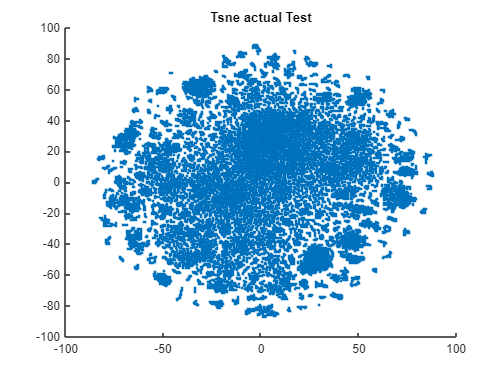

% figure tsne
figure
scatter(tsne_actualTest(:,1), tsne_actualTest(:,2), '.')
title('Tsne actual Test')

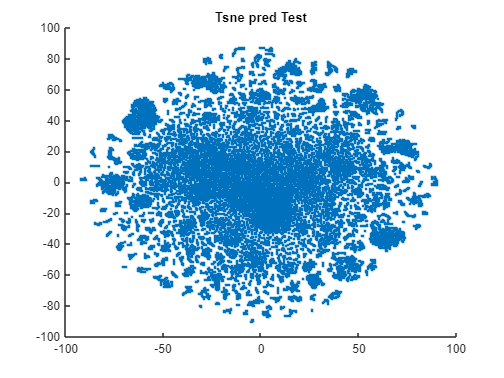



figure
scatter(tsne_predTest(:,1), tsne_predTest(:,2), '.')
title('Tsne pred Test')

## ------ TRY Another net ------

## Predict network TEST data

It seems that the encoder decoder worked well, as seen from the pca data, so let's predic the test data too

% yPredTrain = predict(net, xTrain);
yPredTrain_new_test = predict(net_decoder, xTest);


% normalize
predictTese_new_test = yPredTrain_new_test.*sigma + mu;
actualTest = yTest.*sigma + mu;
RMSE_Test_new_test = real(sqrt(mean((actualTest - predictTese_new_test).^2)))

RMSE_Test_new_test = 1×66 single row vector
    0.1100    0.1804    0.1979    0.1670    0.2284    0.2546    0.2285    0.2348    0.3111    0.3508    0.3430    0.3242    0.2823    0.3053    0.3494    0.0976    0.2107    0.2026    0.1905    0.2101    0.3306    0.3081    0.3446    0.3230    0.3752    0.4002    0.4265    0.3348    0.3438    0.3307    0.4654    0.5681    0.2878    0.3720    0.4801    0.4510    0.5426    0.6033    0.6076    0.6093    0.3977    0.3998    0.4295    0.3425    0.3717    0.4729    0.4469    0.4544    0.4926    0.4632


## Do PCA

rng default
% Do dim reduction to compare both types of predictions
[~,pca_big_new_test,  ~, ~, explained_test] = pca(predictTese_new_test, 'NumComponents',3);
[~, pca_real_test, ~, ~, explained_ac] = pca(actualTest, 'NumComponents',3);
mean_RMSE = mean(RMSE_Test_new_test(1:find(cumsum(explained_test) > 80, 1, 'first')));
disp([ 'mean RMSE to 80% var: ', num2str(mean_RMSE)])

mean RMSE to 80% var: 0.26388


### Figure PCA - Test data

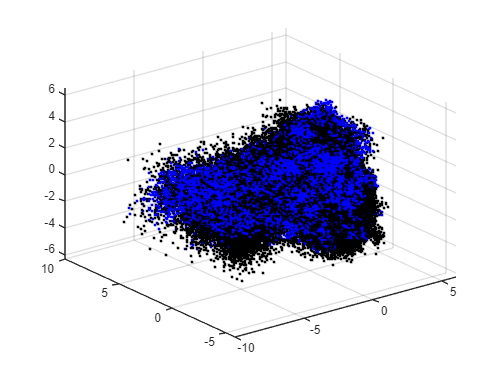

close;
figure
cla
scatter3(pca_real_test(:,1),pca_real_test(:,2),pca_real_test(:,3),'k.') %
hold on
scatter3(-pca_big_new_test(:,1), pca_big_new_test(:,2),pca_big_new_test(:,3), 'b.') %  
hold off

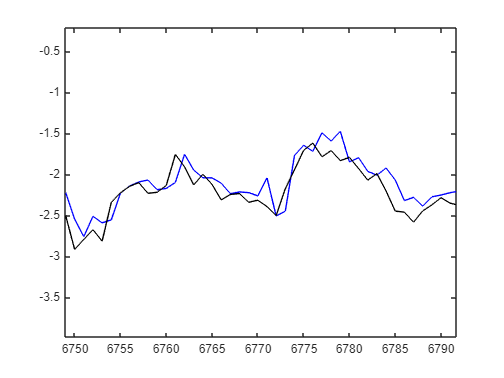


figure, 
plot(pca_big_new_test(:,1), 'b')
hold on
plot(-pca_real_test(:,1), 'k')

Do tsne on test data

rng default
tsne_actualTest = tsne(actualTest, 'Verbose',1);


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.774032e+01 |    6.988320e-09 |
|       40 |    3.774032e+01 |    8.905181e-08 |
|       60 |    3.773957e+01 |    4.362921e-06 |
|       80 |    3.656440e+01 |    2.043594e-05 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    6.717717e+00 |    1.136392e-05 |
|      120 |    6.100885e+00 |    1.033679e-05 |
|      140 |    5.743382e+00 |    7.991832e-06 |
|      160 |    5.484270e+00 |    8.101394e-06 |
|      180 |    5.278678e+00 |    9.430621e-06 |
|      200 |    5.106371e+00 |    8.414915e-06 |
|      220 |    4.

disp(' ----- ')

 ----- 


tsne_predTest = tsne(predictTese_new_test, 'Verbose',1);


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.561174e+01 |    7.196748e-09 |
|       40 |    3.561174e+01 |    7.400194e-08 |
|       60 |    3.561134e+01 |    4.097127e-06 |
|       80 |    3.429087e+01 |    2.386067e-05 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    6.375770e+00 |    1.057837e-05 |
|      120 |    5.791256e+00 |    9.803123e-06 |
|      140 |    5.454527e+00 |    9.004392e-06 |
|      160 |    5.209742e+00 |    1.091362e-05 |
|      180 |    5.015324e+00 |    8.439418e-06 |
|      200 |    4.852805e+00 |    1.001172e-05 |
|      220 |    4.

disp('tsne done')

tsne done


% figure tsne
figure
scatter(tsne_actualTest(:,1), tsne_actualTest(:,2), '.')
title('Tsne actual Test')

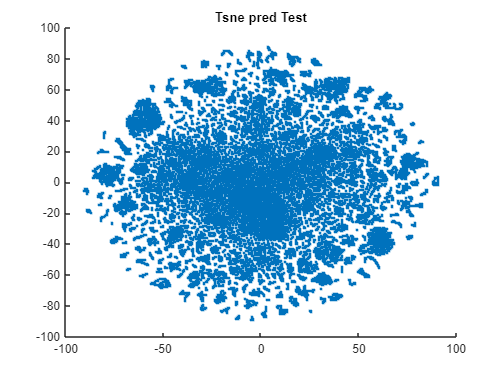



figure
scatter(tsne_predTest(:,1), tsne_predTest(:,2), '.')
title('Tsne pred Test')

# Change sliding window  and predict in >1 frames

% % Prepare data for 30-frame prediction
% % 1. Data Preparation
% input_window = 1000;  % number of input steps
% output_window = 10;  % number of prediction steps (can be changed)
% block_len = input_window + output_window;
% 
% % 
% % [features_30, responses_30] = create_inout_sequences(xNorm, input_window, output_window)
% tic% Correct window creation
% % Correct window creation with parallelization
% % Correct window creation with parallelization
data = xNorm;
% nrows = size(data,1) - input_window;  % Remove the +1
% % features_100 = cell(nrows, 1);
% % responses_100 = cell(nrows, 1);
% 
% % Define chunk size for parallel processing
% chunkSize = 1000;
% numChunks = ceil(nrows/chunkSize);
% 
% % Pre-allocate a cell array to store chunk results
% chunk_features = cell(numChunks, 1);
% chunk_responses = cell(numChunks, 1);
% 
% parfor chunk = 1:numChunks
%     % Calculate indices for this chunk
%     startIdx = (chunk-1)*chunkSize + 1;
%     endIdx = min(chunk*chunkSize, nrows);
%     num_windows = endIdx - startIdx + 1;
% 
%     % Initialize temporary cell arrays for this chunk
%     temp_features = cell(num_windows, 1);
%     temp_responses = cell(num_windows, 1);
% 
%     % Process windows in this chunk
%     for i = 1:num_windows
%         global_idx = startIdx + i - 1;
%         % Input sequence: replace last 'output_window' elements with zeros
%         input_seq = data(global_idx:global_idx+input_window-1, :);
%         input_seq(end-output_window+1:end, :) = 0;
%         temp_features{i} = input_seq'; % [numFeatures x input_window]
% 
%         % Target sequence: original data
%         temp_responses{i} = data(global_idx:global_idx+input_window-1, :)'; % [numFeatures x input_window]
%     end
% 
%     % Store chunk results
%     chunk_features{chunk} = temp_features;
%     chunk_responses{chunk} = temp_responses;
% end
% 
% % Combine chunks
% features_100 = vertcat(chunk_features{:});
% responses_100 = vertcat(chunk_responses{:});
% 
% % The rest remains the same
% xTest_30 = features_100(end-nTest+1:end,:);
% yTest_30 = responses_100(end-nTest+1:end,:);
% xTrain_30 = features_100(1:end-nTest,:);
% yTrain_30 = responses_100(1:end-nTest,:);
% toc

input_window = 1000;    % Input sequence length
output_window = 5;     % Prediction window length
stride = 5;            % Window sliding step (for non-overlapping targets)

% Calculate number of valid sequences
total_data_points = size(data, 1);
nrows = floor((total_data_points - input_window) / stride) + 1;

% Data preparation with proper windowing
features_100 = cell(nrows, 1);
responses_100 = cell(nrows, 1);

for i = 1:nrows
    % Calculate window position
    start_idx = (i-1)*stride + 1;
    end_idx = start_idx + input_window - 1;
    
    % Extract and process input sequence
    input_seq = data(start_idx:end_idx, :);
    zero_mask = input_seq;
    zero_mask(end-output_window+1:end, :) = 0;  % Zero last 10 frames
    
    % Store feature (zeroed sequence) and response (original last 10 frames)
    features_100{i} = zero_mask';
    responses_100{i} = input_seq';
end


% Original nTest calculation (presumably) was based on the number of sequences with stride=1
original_nTest = nTest;  % Store the original value

% Calculate how many sequences we'd have with stride=1
sequences_stride1 = size(data,1) - input_window + 1;

% Calculate how many sequences we have with stride=100
sequences_stride100 = floor((size(data,1) - input_window) / stride) + 1;

% Adjust nTest proportionally
nTest_adjusted = ceil((original_nTest / sequences_stride1) * sequences_stride100);

% Use the adjusted value for splitting
xTest_30 = features_100(end-nTest_adjusted+1:end,:);
yTest_30 = responses_100(end-nTest_adjusted+1:end,:);
xTrain_30 = features_100(1:end-nTest_adjusted,:);
yTrain_30 = responses_100(1:end-nTest_adjusted,:);

## Select network and modify it

numFeatures = nFeatures;
numHeads = 4; 
numKeyChannels = 256; 
feedforwardHiddenSize = 512; 
modelHiddenSize = 256; 
maxSequenceLength = 1000;


lgraph = layerGraph();
% 
% decoderLayers = [ 
%     sequenceInputLayer(numFeatures, Name="in")
%     fullyConnectedLayer(modelHiddenSize, Name="embedding")
%     positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="position_embed") 
%     additionLayer(2, Name="embed_add") 
%     layerNormalizationLayer(Name="embed_norm") 
%     selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal") 
%     additionLayer(2, Name="attention_add") 
%     layerNormalizationLayer(Name="attention_norm") 
%     fullyConnectedLayer(feedforwardHiddenSize) 
%     geluLayer 
%     fullyConnectedLayer(modelHiddenSize) 
%     additionLayer(2, Name="feedforward_add") 
%     layerNormalizationLayer(Name="decoder1_norm") 
%     selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal") 
%     additionLayer(2, Name="attention2_add") 
%     layerNormalizationLayer(Name="attention2_norm") 
%     fullyConnectedLayer(feedforwardHiddenSize) 
%     geluLayer 
%     fullyConnectedLayer(modelHiddenSize) 
%     additionLayer(2, Name="feedforward2_add") 
%     layerNormalizationLayer(Name="decoder2_norm") 
%     lstmLayer(128,"Name","lstm",OutputMode="sequence")
%     fullyConnectedLayer(numFeatures, Name="head")
%      % fullyConnectedLayer(66*30, Name="head")  
%          % flattenLayer('Name', 'flatten_output')
%     regressionLayer(Name="regressionoutput")];
% 
% % 2. Modified Network
decoderLayers = [
    sequenceInputLayer(numFeatures, Name="in")
    fullyConnectedLayer(modelHiddenSize, Name="embedding")
    positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="position_embed") 
    additionLayer(2, Name="embed_add") 
    layerNormalizationLayer(Name="embed_norm") 
    selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal") 
    additionLayer(2, Name="attention_add") 
    layerNormalizationLayer(Name="attention_norm") 
    fullyConnectedLayer(feedforwardHiddenSize) 
    geluLayer 
    fullyConnectedLayer(modelHiddenSize) 
    additionLayer(2, Name="feedforward_add") 
    layerNormalizationLayer(Name="decoder1_norm") 
    selfAttentionLayer(numHeads, numKeyChannels, AttentionMask="causal") 
    additionLayer(2, Name="attention2_add") 
    layerNormalizationLayer(Name="attention2_norm") 
    fullyConnectedLayer(feedforwardHiddenSize) 
    geluLayer 
    fullyConnectedLayer(modelHiddenSize) 
    additionLayer(2, Name="feedforward2_add") 
    layerNormalizationLayer(Name="decoder2_norm") 
    lstmLayer(128, "Name", "lstm", "OutputMode", "sequence") % Output sequence
    fullyConnectedLayer(numFeatures, Name="head")
    MaskedMSELayer(output_window, 'masked_mse') % Custom loss layer so far located in Desktop
];

lgraph = addLayers(lgraph,decoderLayers);

lgraph = connectLayers(lgraph,"embedding","embed_add/in2");
lgraph = connectLayers(lgraph,"embed_norm","attention_add/in2");
lgraph = connectLayers(lgraph,"attention_norm","feedforward_add/in2");
lgraph = connectLayers(lgraph,"decoder1_norm","attention2_add/in2");
lgraph = connectLayers(lgraph,"attention2_norm","feedforward2_add/in2");
% 
% lgraph = connectLayers(lgraph,"embedding","embed_add/in2");
% lgraph = connectLayers(lgraph,"embed_norm","attention_add/in2");
% lgraph = connectLayers(lgraph,"attention_norm","feedforward_add/in2");
% lgraph = connectLayers(lgraph,"decoder1_norm","attention2_add/in2");
% lgraph = connectLayers(lgraph,"attention2_norm","feedforward2_add/in2");

lgraph_decoder_30 = lgraph;

numTransformerBlocks = 4;  % Number of transformer blocks
% Network parameters
numTransformerBlocks = 4;      % Number of transformer blocks
mlpUnits = [128 64];          % Size of MLP layers after transformer
% Network parameters
numTransformerBlocks = 4;  % Number of transformer blocks
mlpUnits = [128 64];      % Size of MLP layers after transformer

% encoder and decoder
lgraph = layerGraph();

% Single input 
initialLayers = [
    sequenceInputLayer(numFeatures, Name="in")];
lgraph = addLayers(lgraph, initialLayers);

% Encoder path initial layers
encoderInitial = [
    fullyConnectedLayer(modelHiddenSize, Name="encoder_embedding")
    positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="encoder_pos_embed")
    additionLayer(2, Name="encoder_embed_add")
    layerNormalizationLayer(Name="encoder_embed_norm")];

lgraph = addLayers(lgraph, encoderInitial);
lgraph = connectLayers(lgraph, "in", "encoder_embedding");
lgraph = connectLayers(lgraph, "encoder_embedding", "encoder_embed_add/in2");

% Encoder blocks
for i = 1:numTransformerBlocks
    blockName = "encoder_block" + i;
    
    encoderBlock = [
        selfAttentionLayer(numHeads, modelHiddenSize, Name=blockName+"_attention")
        additionLayer(2, Name=blockName+"_attention_add")
        layerNormalizationLayer(Name=blockName+"_attention_norm")
        fullyConnectedLayer(feedforwardHiddenSize, Name=blockName+"_ff1")
        geluLayer(Name=blockName+"_gelu")
        fullyConnectedLayer(modelHiddenSize, Name=blockName+"_ff2")
        additionLayer(2, Name=blockName+"_ffn_add")
        layerNormalizationLayer(Name=blockName+"_final_norm")];
    
    lgraph = addLayers(lgraph, encoderBlock);
    
    if i == 1
        lgraph = connectLayers(lgraph, "encoder_embed_norm", blockName+"_attention");
    else
        prevBlock = "encoder_block" + (i-1) + "_final_norm";
        lgraph = connectLayers(lgraph, prevBlock, blockName+"_attention");
    end
    
    lgraph = connectLayers(lgraph, blockName+"_attention", blockName+"_attention_add/in2");
    lgraph = connectLayers(lgraph, blockName+"_attention_norm", blockName+"_ffn_add/in2");
end

encoderFinalLayer = "encoder_block" + numTransformerBlocks + "_final_norm";

% Decoder path initial layers
decoderInitial = [
    fullyConnectedLayer(modelHiddenSize, Name="decoder_embedding")
    positionEmbeddingLayer(modelHiddenSize, maxSequenceLength, Name="decoder_pos_embed")
    additionLayer(2, Name="decoder_embed_add")
    layerNormalizationLayer(Name="decoder_embed_norm")];

lgraph = addLayers(lgraph, decoderInitial);
lgraph = connectLayers(lgraph, "in", "decoder_embedding");
lgraph = connectLayers(lgraph, "decoder_embedding", "decoder_embed_add/in2");

% Decoder blocks
for i = 1:numTransformerBlocks
    blockName = "decoder_block" + i;
    
    decoderBlock = [
        % Self-attention with causal mask
        selfAttentionLayer(numHeads, modelHiddenSize, Name=blockName+"_self_attention", AttentionMask="causal")
        additionLayer(2, Name=blockName+"_attention_add")
        layerNormalizationLayer(Name=blockName+"_attention_norm")
        
        % Attention with encoder output (encoder-decoder attention)
        selfAttentionLayer(numHeads, modelHiddenSize, Name=blockName+"_enc_dec_attention")
        additionLayer(2, Name=blockName+"_enc_dec_add")
        layerNormalizationLayer(Name=blockName+"_enc_dec_norm")
        
        % Feed-forward network
        fullyConnectedLayer(feedforwardHiddenSize, Name=blockName+"_ff1")
        geluLayer(Name=blockName+"_gelu")
        fullyConnectedLayer(modelHiddenSize, Name=blockName+"_ff2")
        additionLayer(2, Name=blockName+"_ffn_add")
        layerNormalizationLayer(Name=blockName+"_final_norm")];
    
    lgraph = addLayers(lgraph, decoderBlock);
    
    if i == 1
        lgraph = connectLayers(lgraph, "decoder_embed_norm", blockName+"_self_attention");
    else
        prevBlock = "decoder_block" + (i-1) + "_final_norm";
        lgraph = connectLayers(lgraph, prevBlock, blockName+"_self_attention");
    end
    
    % Connect encoder output to encoder-decoder attention
    % lgraph = connectLayers(lgraph, encoderFinalLayer, blockName+"_enc_dec_attention");
    % lgraph = connectLayers(lgraph, encoderFinalLayer, blockName+"_enc_dec_attention/Value");
    
    % Residual connections
    lgraph = connectLayers(lgraph, blockName+"_self_attention", blockName+"_attention_add/in2");
    lgraph = connectLayers(lgraph, blockName+"_enc_dec_attention", blockName+"_enc_dec_add/in2");
    lgraph = connectLayers(lgraph, blockName+"_enc_dec_norm", blockName+"_ffn_add/in2");
end

% Output layers with layer normalization
outputLayers = [
    layerNormalizationLayer(Name="output_norm")
    fullyConnectedLayer(numFeatures, Name="output_projection")
    MaskedMSELayer(output_window, "masked_mse")
];

lgraph = addLayers(lgraph, outputLayers);
lgraph_big_e_d = connectLayers(lgraph, "decoder_block"+numTransformerBlocks+"_final_norm", "output_norm");

function net = configureNetworkMode(net, isTraining)
    if isTraining
        net = activateLayer(net, "decoder_input_switch", 1);  % Use teacher forcing
    else
        net = activateLayer(net, "decoder_input_switch", 2);  % Use autoregressive predictions
    end
end
% lgraph_big_e_d = connectLayers(lgraph, "decoder_block"+numTransformerBlocks+"_final_norm", "lstm");


maxEpochs = 40;
miniBatchSize = 164;%32;
learningRate = 0.001;
solver = 'adam';
shuffle = 'every-epoch';
gradientThreshold = 10;
executionEnvironment = "gpu";

options = trainingOptions(solver, ...
    'Plots','training-progress', ...
    'MaxEpochs', maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', shuffle, ...
    'InitialLearnRate', learningRate, ...
    'GradientThreshold', gradientThreshold, ...
    'SequenceLength', input_window, ...          % Add this for variable sequences
    'SequencePaddingValue', 0, ...           % Add this for padding
    'ExecutionEnvironment', executionEnvironment,...
    'Verbose', 0,...
    'CheckpointPath', fullfile('C:\Users\acuna\Desktop\Training_poses\'));


Train

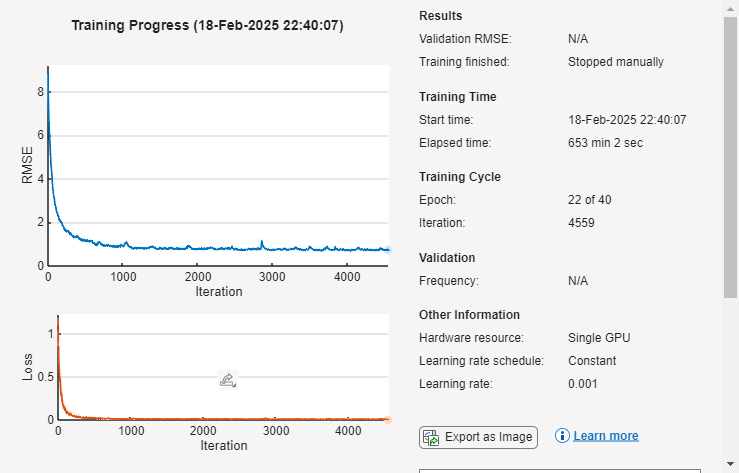

netdecode30_2 = trainNetwork(xTrain_30,yTrain_30,lgraph_decoder_30,options);

% save('custom_net.mat', 'layers', 'learnables');
%% Predict
yTrain_pred_decode_30_2 = predict(netdecode30_2, xTrain_30(1));
yTest_pred_decode_30_2 =  predict(netdecode30_2, xTest_30(1));
% 
% save('yTrain_pred_decode_30_2.mat', 'yTrain_pred_decode_30_2', '-v7.3'); save('yTest_pred_decode_30_2.mat', 'yTest_pred_decode_30_2', '-v7.3')

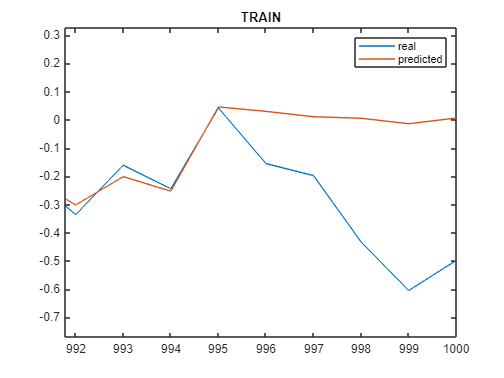

fr = 1;
feat = 61;
x = yTrain_30;
y = yTrain_pred_decode_30_2;
h = plot_predictions(fr, feat, x, y);
title('TRAIN')

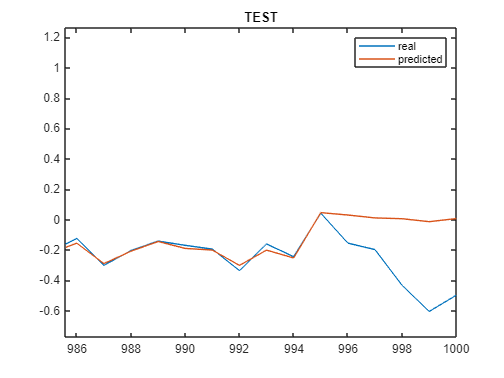

x = yTest_30;
y = yTest_pred_decode_30_2;
h2 = plot_predictions(fr, feat, x, y);
title('TEST')

Train encoder and decoder net

% net_bieg_emcode_decode30 = trainNetwork(xTrain_30,yTrain_30,lgraph,options);
% 
% yTrain_pred_enc_dec_30 = predict(net_bieg_emcode_decode30, yTrain_30);
% yTest_pred_enc_dec_30 =  predict(net_bieg_emcode_decode30, yTest_30);

Compute the mean RMSE across predicted windows

% Assume yPredTest and yTest are cell arrays where each cell contains a matrix
% of size [numFeatures x seqLength] corresponding to one sliding window prediction.
% OutputWindow is the number of future frames on which you want to evaluate RMSE.

% output_window = 10; % Change to 5 if you want to evaluate the last 5 frames

squaredErrors = [];  % Initialize array to collect squared errors
ERRORS = squaredErrors;
numSeq = numel(yTrain_pred_decode_30_2);  % Total number of sliding windows

for i = 1:numSeq
    % Extract the prediction and corresponding target sequence
    predSeq = yTrain_pred_decode_30_2{i};  % [numFeatures x seqLength]
    trueSeq = yTrain_30{i};      % [numFeatures x seqLength]
    
    % Determine the sequence length
    seqLength = size(predSeq, 2);
    
    % Check to ensure the sequence is long enough for the output window
    if seqLength < output_window
        error('Sequence length (%d) is less than OutputWindow (%d) in sequence %d.', seqLength, output_window, i);
    end
    
    % Extract only the last OutputWindow frames from both prediction and target
    predMasked = predSeq(:, seqLength - output_window + 1:end);
    trueMasked = trueSeq(:, seqLength - output_window + 1:end);
    
    % Compute the squared error for this window and accumulate it
    squaredErrors = [squaredErrors; (predMasked - trueMasked).^2];

    ERRORS = [ERRORS; errors_T];
    squaredErrors = [squaredErrors; (predMasked - trueMasked).^2];
end

% Calculate the RMSE across all windows and frames
rmse = sqrt(mean(squaredErrors(:)));
fprintf('RMSE computed over the last %d frames: %f\n', output_window, rmse);

RMSE computed over the last 10 frames: 0.412456


rmse_train_feat =  (mean(ERRORS))';

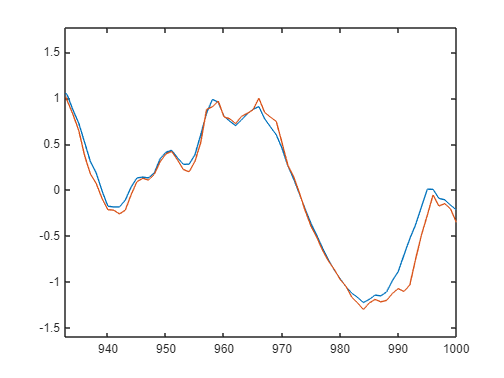

% plot the predictions
fr = 1;
feat = 1;
figure
plot(yTrain_30{fr}(feat,:))
hold on
plot(yTrain_pred_decode_30_2{fr}(feat,:))

% RSME For test  dataset
% output_window = 10; % Change to 5 if you want to evaluate the last 5 frames

squaredErrors = [];  % Initialize array to collect squared errors

numSeq = numel(yTest_pred_decode_30_2);  % Total number of sliding windows
ERRORS_test = [];
for i = 1:numSeq
    % Extract the prediction and corresponding target sequence
    predSeq = yTest_pred_decode_30_2{i};  % [numFeatures x seqLength]
    trueSeq = yTest_30{i};      % [numFeatures x seqLength]
    
    % Determine the sequence length
    seqLength = size(predSeq, 2);
    
    % Check to ensure the sequence is long enough for the output window
    if seqLength < output_window
        error('Sequence length (%d) is less than OutputWindow (%d) in sequence %d.', seqLength, output_window, i);
    end
    
    % Extract only the last OutputWindow frames from both prediction and target
    predMasked = predSeq(:, seqLength - output_window + 1:end);
    trueMasked = trueSeq(:, seqLength - output_window + 1:end);
    
    % Compute the squared error for this window and accumulate it
    errors = (predMasked - trueMasked).^2;
    errors_T = mean(errors, 2)';
    ERRORS_test = [ERRORS_test; errors_T];
    squaredErrors = [squaredErrors; (predMasked - trueMasked).^2];
end

% Calculate the RMSE across all windows and frames
rmse_test = sqrt(mean(squaredErrors(:)));
fprintf('RMSE computed over the last %d frames: %f\n', output_window, rmse_test);

RMSE computed over the last 10 frames: 0.385325



rmse_test_feat =  (mean(ERRORS_test))';
% fprintf('RMSE per Feature computed over the last %d frames: %f\n', output_window, rmse_test_feat);

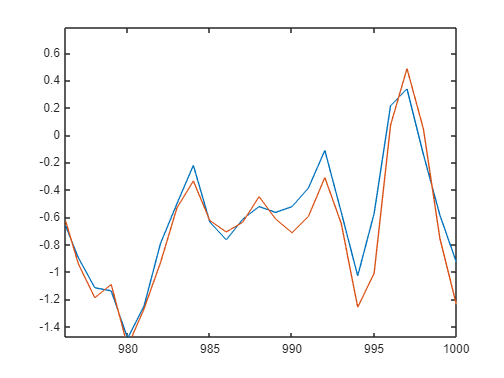

% plot the predictions
fr = 10801;
feat = 2;
figure
plot(yTest_30{fr}(feat,:))
hold on
plot(yTest_pred_decode_30_2{fr}(feat,:))

# Run a window of larger value


input_window = 1000;    % Input sequence length
output_window = 120;     % Prediction window length
stride = 10;            % Window sliding step (for non-overlapping targets)

% Calculate number of valid sequences
total_data_points = size(data, 1);
nrows = floor((total_data_points - input_window) / stride) + 1;

% Data preparation with proper windowing
features_120 = cell(nrows, 1);
responses_120 = cell(nrows, 1);

for i = 1:nrows
    % Calculate window position
    start_idx = (i-1)*stride + 1;
    end_idx = start_idx + input_window - 1;
    
    % Extract and process input sequence
    input_seq = data(start_idx:end_idx, :);
    zero_mask = input_seq;
    zero_mask(end-output_window+1:end, :) = 0;  % Zero last 10 frames
    
    % Store feature (zeroed sequence) and response (original last 10 frames)
    features_120{i} = zero_mask';
    responses_120{i} = input_seq';
end


% Original nTest calculation (presumably) was based on the number of sequences with stride=1
original_nTest = nTest;  % Store the original value

% Calculate how many sequences we'd have with stride=1
sequences_stride1 = size(data,1) - input_window + 1;

% Calculate how many sequences we have with stride=100
sequences_stride100 = floor((size(data,1) - input_window) / stride) + 1;

% Adjust nTest proportionally
nTest_adjusted = ceil((original_nTest / sequences_stride1) * sequences_stride100);

% Use the adjusted value for splitting
xTest_120 = features_120(end-nTest_adjusted+1:end,:);
yTest_120= responses_120(end-nTest_adjusted+1:end,:);
xTrain_120 = features_120(1:end-nTest_adjusted,:);
yTrain_120 = responses_120(1:end-nTest_adjusted,:);


%

 TRain

netdecode120_2 = trainNetwork(xTrain_120,yTrain_120,lgraph_decoder_30,options);
% save('custom_net.mat', 'layers', 'learnables');
%% Predict
yTrain_pred_decode_120_2 = predict(netdecode120_2, xTrain_120);
yTest_pred_decode_120_2 =  predict(netdecode120_2, xTest_120);
% 
save('yTrain_pred_decode_120_2.mat', 'yTrain_pred_decode_120_2', '-v7.3'); save('yTest_pred_decode_120_2.mat', 'yTest_pred_decode_120_2', '-v7.3')

% Save net
net_filename = ("C:\Users\acuna\Desktop\Training_poses\_last_120\_net_final.mat")
save(net_filename, 'netdecode120_2', '-v7.3') 

[rmse_global_train, rmse_feat_train] = calculate_rmse(yTrain_pred_decode_120_2, yTrain_120, output_window)

rmse_global_train = single
0.0999

rmse_feat_train = 66×1 single column vector
    0.0792
    0.0968
    0.0903
    0.0856
    0.1015
    0.0914
    0.0939
    0.0869
    0.0978
    0.0907


[rmse_global_test, rmse_feat_test] = calculate_rmse(yTest_pred_decode_120_2, yTest_120, output_window)

rmse_global_test = single
0.1008

rmse_feat_test = 66×1 single column vector
    0.0863
    0.0974
    0.0982
    0.0825
    0.1027
    0.0878
    0.0983
    0.0985
    0.0929
    0.0912


Plot example predictions and actual data

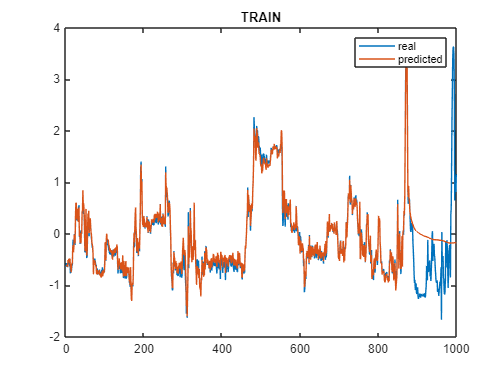

fr = 1312;
feat = 61;
x = yTrain_120;
y = yTrain_pred_decode_120_2;
h = plot_predictions(fr, feat, x, y);
title('TRAIN')

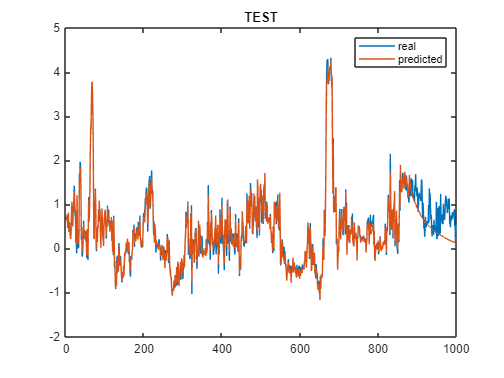

x = yTest_120;
y = yTest_pred_decode_120_2;
h2 = plot_predictions(fr, feat, x, y);
title('TEST')

% Here's how to load the network completely. 
% Load net
addpath('C:\Users\acuna\Desktop\')
% example
filename = "C:\Users\acuna\Desktop\Training_poses\_last_10\net_checkpoint__104__2025_02_17__23_35_06.mat";
net = coder.loadDeepLearningNetwork(filename);
classNames = net.Layers(end);


rng default
% Do dim reduction to compare both types of predictions
[~,pca_big_new_test,  ~, ~, e] = pca(yTest_pred_decode_30_2, 'NumComponents',3);
[~, pca_real_test, ~, ~, explained_ac] = pca(actualTrain, 'NumComponents',3);
mean_RMSE = mean(RMSE_Test_new_test(1:find(cumsum(e) > 80, 1, 'first')));
disp([ 'mean RMSE to 80% var: ', num2str(mean_RMSE)])

mean RMSE to 80% var: 0.27222


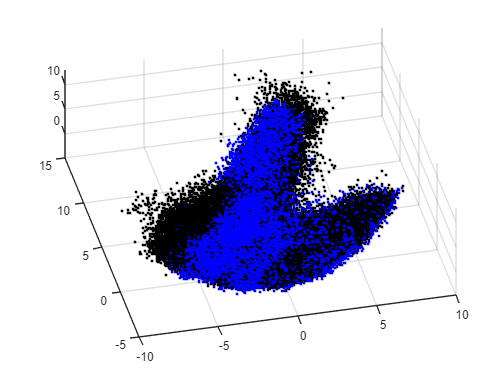

close;
figure
cla
scatter3(pca_real_test(:,1),pca_real_test(:,2),pca_real_test(:,3),'k.') %
hold on
scatter3(pca_big_new_test(:,1), pca_big_new_test(:,2),pca_big_new_test(:,3), 'b.') %  
hold off

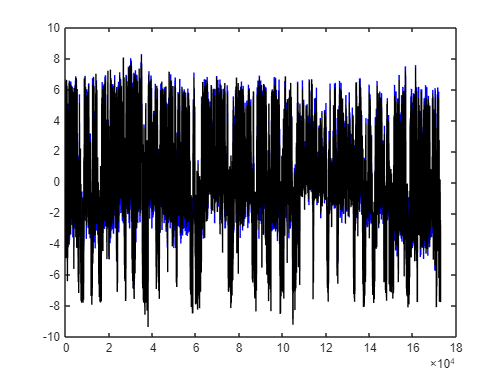


figure, 
plot(pca_big_new_test(:,1), 'b')
hold on
plot(pca_real_test(:,1), 'k')

rng default
tsne_actual = tsne(actualTrain, 'Verbose',1);


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.954248e+01 |    3.836507e-09 |
|       40 |    3.954248e+01 |    1.119346e-08 |
|       60 |    3.954248e+01 |    1.440201e-07 |
|       80 |    3.954082e+01 |    4.674786e-06 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    8.335055e+00 |    1.062275e-05 |
|      120 |    7.325456e+00 |    8.972619e-06 |
|      140 |    6.829882e+00 |    8.781284e-06 |
|      160 |    6.527600e+00 |    1.096926e-05 |
|      180 |    6.304235e+00 |    7.946743e-06 |
|      200 |    6.124621e+00 |    6.904290e-06 |
|      220 |    5.

disp(' ----- ')

 ----- 


tsne_pred = tsne(predictTrain_dec_30, 'Verbose',1);


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.965929e+01 |    3.421558e-09 |
|       40 |    3.965929e+01 |    1.269873e-08 |
|       60 |    3.965929e+01 |    1.329576e-07 |
|       80 |    3.965654e+01 |    4.939492e-06 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    8.311393e+00 |    1.088069e-05 |
|      120 |    7.297305e+00 |    9.781126e-06 |
|      140 |    6.816086e+00 |    7.495504e-06 |
|      160 |    6.519039e+00 |    6.720506e-06 |
|      180 |    6.298088e+00 |    6.345109e-06 |
|      200 |    6.119515e+00 |    5.867331e-06 |
|      220 |    5.

disp('tsne done')

tsne done


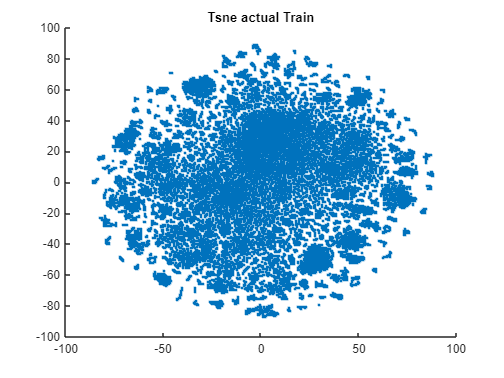

% figure tsne
figure
scatter(tsne_actualTest(:,1), tsne_actualTest(:,2), '.')
title('Tsne actual Train')

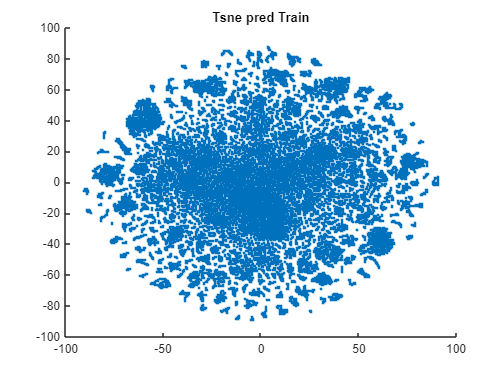



figure
scatter(tsne_predTest(:,1), tsne_predTest(:,2), '.')
title('Tsne pred Train')

Plotting test predictions

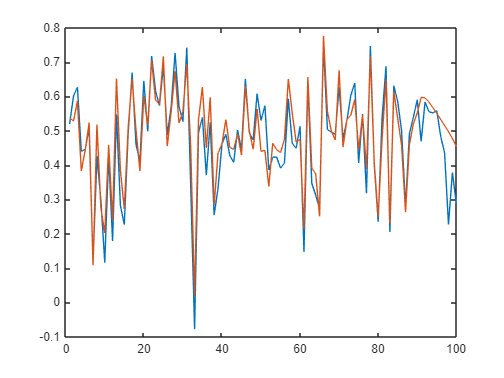

% Create input by zeroing last output_window frames
idx_to_test = 800;
feat_to_test = 65;

current_seq = xTest_30{idx_to_test};                           
input_seq = current_seq;
input_seq(:, end-output_window+1:end) = 0;

% predict
 % Get prediction
 pred = predict(netdecode30, input_seq);
 act = yTest_30{idx_to_test};

 % Plot it
 figure, 
 plot(act(feat_to_test,:))
 hold on
 plot(pred(feat_to_test,:))

 function h = plot_predictions(fr, feat, x, y)
 % plot the predictions
 h = figure;
 plot(x{fr}(feat,:))
 hold on
 plot(y{fr}(feat,:))
 legend({'real', 'predicted'})
 end

function [rmse_global, rmse_feat] = calculate_rmse(pred_data, y_data, output_window)
    % CALCULATE_RMSE Calculates global RMSE and per-feature RMSE for sequential data
    %
    % Inputs:
    %   pred_data - Cell array of predictions, each cell containing a matrix of size [numFeatures x seqLength]
    %   y_data - Cell array of ground truth data, each cell containing a matrix of size [numFeatures x seqLength]
    %   output_window - Number of frames at the end of sequence to evaluate (default: 10)
    %
    % Outputs:
    %   rmse_global - Global RMSE across all features and sequences
    %   rmse_feat - RMSE per feature
    
    % Input validation
    if nargin < 3
        output_window = 10;  % Default output window
    end
    
    if ~iscell(pred_data) || ~iscell(y_data)
        error('pred_data and y_data must be cell arrays');
    end
    
    if numel(pred_data) ~= numel(y_data)
        error('Number of sequences in pred_data and y_data must match');
    end
    
    squaredErrors = [];  % Initialize array for squared errors
    ERRORS_test = [];   % Initialize array for per-feature errors
    
    numSeq = numel(pred_data);  % Total number of sliding windows
    
    for i = 1:numSeq
        % Extract prediction and target sequence
        predSeq = pred_data{i};
        trueSeq = y_data{i};
        
        % Validate sequence dimensions
        if ~isequal(size(predSeq), size(trueSeq))
            error('Prediction and target dimensions must match for sequence %d', i);
        end
        
        % Get sequence length
        seqLength = size(predSeq, 2);
        
        % Validate sequence length
        if seqLength < output_window
            error('Sequence length (%d) is less than output_window (%d) in sequence %d.', ...
                  seqLength, output_window, i);
        end
        
        % Extract last output_window frames
        predMasked = predSeq(:, seqLength - output_window + 1:end);
        trueMasked = trueSeq(:, seqLength - output_window + 1:end);
        
        % Compute errors
        errors = (predMasked - trueMasked).^2;
        errors_T = mean(errors, 2)';
        ERRORS_test = [ERRORS_test; errors_T];
        squaredErrors = [squaredErrors; (predMasked - trueMasked).^2];
    end
    
    % Calculate global RMSE
    rmse_global = sqrt(mean(squaredErrors(:)));
    
    % Calculate per-feature RMSE
    rmse_feat = sqrt(mean(ERRORS_test))';
end

function [features, responses] = create_inout_sequences(data, input_window, output_window)
     nrows = size(data,1) - input_window + 1;
    features = cell(nrows, 1);
    responses = cell(nrows, 1);
    
    for i = 1:nrows
        % Input sequence: replace last 'output_window' elements with zeros
        input_seq = data(i:i+input_window-1, :);
        input_seq(end-output_window+1:end, :) = 0;
        features{i} = input_seq'; % [numFeatures x input_window]
        
        % Target sequence: original data
        responses{i} = data(i:i+input_window-1, :)'; % [numFeatures x input_window]
    end
end

Create a custom layer to compute loss only on the last output_window elements.

function [data, mu, sigma] = standardizeByCol(data)
    [n, ~] = size(data);
    mu = mean(data, 1);
    sigma = std(data, 1);
    data = (data - repmat(mu,n,1)) ./ repmat(sigma,n,1);
end